# 4-6-2016 - Multisubject Anova Analysis 

close all;clear all;clc
Z_Constants;
SUB_DIR = fullfile(myGetenv('subject_dir'));
OUTPUT_DIR = fullfile(myGetenv('OUTPUT_DIR'));

anovaBetaMags5 = [];
anovaBetaMags3 = [];
anovaBetaMags1 = [];
anovaBetaBase = [];
anovaBetaSID = {};
anovaNumStims = {};
anovaTotalMags = [];
anovaChan = {};
anovaType = {};
answer = input('use zscore or raw values? Enter "zscore" or "raw"  \n','s');

% exclude playback for now
    sid = SIDS{8}

sid = 702d24

    switch sid
        case 'd5cd55'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','d5cd55epSTATSsig'))
            stims = [54 62];
            goods = [35 36 37 44 45 46 52 53 55 60 61 63];
            
            betaChan = 53;
            typeCell = {'180'};
                        typeCell = {'180'};

        case 'c91479'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','c91479epSTATSsig'))
            betaChan = 64;
            stims = [55 56];
            goods = [38 39 40 46 47 48 62 64];
            
            typeCell = {'180','0'};
            
        case '7dbdec'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','7dbdecepSTATSsig'))
            stims = [11 12];
            goods = [4 5 10 13 21 22 23];
            
            betaChan = 4;
            typeCell = {'180'};
        case '9ab7ab'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','9ab7abepSTATSsig'))
            betaChan = 51;
            stims = [59 60];
            goods = [42 43 50 51 52 53 57 58];
            typeCell = {'270'};
        case '702d24'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','702d24epSTATSsig'))
            betaChan = 5;
            stims = [13 14];
            %                     goods = 5;
            goods = [4 5 6 12 20 21 22];
            
            typeCell = {'270','90'};
            
        case 'ecb43e'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','ecb43eepSTATSsig'))
            dataForAnova{64} = [];
            CCEPbyNumStim{64} = [];
            ZscoredDataForAnova{64} = [];
            
            betaChan = 55;
            goods = [55 63 54 46 47 48 46];
            stims = [56 64];
            typeCell = {'270','90','Null','Random'};
            
        case '0b5a2e'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','0b5a2eepSTATSsig'))
            betaChan = 23;
            stims = [22 30];
            goods = [12 13 14 15 16 21 23 31 32 39 40];
            typeCell = {'270','90','Null'};
            
        case '0b5a2ePlayback'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','0b5a2ePlaybackepSTATSsig'))
            betaChan = 31;
            stims = [22 30];
            goods = [12 13 14 15 16 21 23 31 32 39 40];
            typeCell = {'270','90','Null'};
            
            
    end
    
    
    
    
    % here's where I pick those channels!
    chan = betaChan;
    chans = betaChan;
    
    % figure out number of test conditions
    numTypes = length(CCEPbyNumStim{1});
    
    if strcmp(sid,'0b5a2e') || strcmp(sid,'0b5a2ePlayback') || strcmp(sid,'ecb43e')
        nullType = 3;
        
    else
        nullType = NaN;
    end
    
    % cells, rather than stacked, of responses for given num stimuli
    
    for chan = chans
        % for each channel, a single stacked vector of all of the responses for a given number of stimuli
        tB = [];
        t1 = [];
        t2 = [];
        t3 = [];
        tN = []; 
        
        switch(answer)
            case 'zscore'
                dataForAnova = ZscoredDataForAnova;
            case 'raw'
                
        end
        
        for i = 1:numTypes
            
            if i ~= nullType
                tempMag = dataForAnova{chan}{i}{1};
                tempLabel = dataForAnova{chan}{i}{2};
                tempKeeps = dataForAnova{chan}{i}{3};
                
                tempBase = tempMag(tempLabel(tempKeeps)==0);
                tempResp1 = tempMag(tempLabel(tempKeeps)==1);
                tempResp2 = tempMag(tempLabel(tempKeeps)==2);
                tempResp3 = tempMag(tempLabel(tempKeeps)==3);
                
                tB = [tB tempBase];
                t1 = [t1 tempResp1];
                t2 = [t2 tempResp2];
                t3 = [t3 tempResp3];
                
                
                
                %             elseif i == nullType && strcmp(sid,'ecb43e') == 0
                %                 tempMag = dataForAnova{chan}{i}{1};
                %                 tempLabel = dataForAnova{chan}{i}{2};
                %                 tempKeeps = dataForAnova{chan}{i}{3};
                %
                %                 tempBase = tempMag(tempLabel(tempKeeps)==0);
                %                 tempRespNull = tempMag(tempLabel(tempKeeps)==1);
                %
                %                 tN = [tN tempRespNull];
                
                
                
            
            lengthType = length(tempBase)+length(tempResp1)+length(tempResp2)+length(tempResp3);
            vecType = repmat(typeCell{i},lengthType,1);
            vecTypeC = cellstr(vecType)';
            anovaType = [anovaType{:} vecTypeC];
            typeResp = [tempResp3 tempResp2 tempResp1 tempBase];
            anovaTotalMags = [anovaTotalMags typeResp];
            num5S = repmat('Ct>=5',length(tempResp3),1);
            num3S= repmat('3<=Ct<=4',length(tempResp2),1);
            num1S = repmat('1<=Ct<=2',length(tempResp1),1);
            numBaseS = repmat('Base',length(tempBase),1);
            
            %             numNullS = repmat('Null',length(tN),1);
            
            b5C = cellstr(num5S)';
            b3C = cellstr(num3S)';
            b1C = cellstr(num1S)';
            BC = cellstr(numBaseS)';
%             nC = cellstr(numNullS)';
            anovaNumStims = [anovaNumStims{:} b5C b3C b1C BC];
            end
        end
        
        % change tihs to just to lnegth(t3) to do the one way anova below
        lengthToRep = length(t3)+length(t2)+length(t1)+length(tB);
        sidString = repmat(sid,lengthToRep,1);
        %         num5S = repmat('Ct>=5',length(t3),1);
        %         num3S= repmat('3<=Ct<=4',length(t2),1);
        %         num1S = repmat('1<=Ct<=2',length(t1),1);
        %         numBaseS = repmat('Base',length(tB),1);
        %
        %         numNullS = repmat('Null',length(tN),1);
        %
        
        sidCell = cellstr(sidString)';
        %         b5C = cellstr(num5S)';
        %         b3C = cellstr(num3S)';
        %         b1C = cellstr(num1S)';
        %         BC = cellstr(numBaseS)';
        %         nC = cellstr(numNullS)';
        
        anovaBetaMags5 = [anovaBetaMags5 t3];
        anovaBetaMags3 = [anovaBetaMags3 t2];
        anovaBetaMags1 = [anovaBetaMags1 t1];
        anovaBetaBase = [anovaBetaBase tB] ;
        anovaBetaSID = [anovaBetaSID{:} sidCell];
%         anovaNumStims = [anovaNumStims{:} b5C b3C b1C BC];
        %         anovaTotalMags = [anovaTotalMags t3 t2 t1 tB];
        %         anovaType = [anovaType typeNums];
        
        
    end
%     [p,tbl,stats] = anova1(anovaBetaMags5,anovaBetaSID)
%     [c,m,h,gnames] = multcompare(stats);


p =     0.0000
    0.5386
       NaN


tbl =     'Source'                                   'Sum Sq.'       'd.f.'    'Singular?'    'Mean Sq.'    'F'          'Prob>F'    
    'anovaNumStims(anovaType,anovaBetaSID)'    [  923.8054]    [   6]    [        0]    [153.9676]    [13.6551]    [6.2864e-15]
    'anovaType(anovaBetaSID)'                  [    4.2664]    [   1]    [        0]    [  4.2664]    [ 0.3784]    [    0.5386]
    'anovaBetaSID'                             [         0]    [   0]    [        0]    [       0]    [      0]    [       NaN]
    'Error'                                    [1.0926e+04]    [ 969]    [        0]    [ 11.2755]           []              []
    'Total'                                    [1.1853e+04]    [ 976]    [        0]            []           []              []


stats =          source: 'anovan'
          resid: [977x1 double]
         coeffs: [12x1 double]
            Rtr: [8x8 double]
       rowbasis: [8x12 double]
            dfe: 969
            mse: 11.2755
    nullproject: [12x8 double]
          terms: [3x3 double]
        nlevels: [3x1 double]
     continuous: [0 0 0]
         vmeans: [3x1 double]
       termcols: [4x1 double]
     coeffnames: {12x1 cell}
           vars: [12x3 double]
       varnames: {3x1 cell}
       grpnames: {3x1 cell}
        vnested: [3x3 double]
            ems: []
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


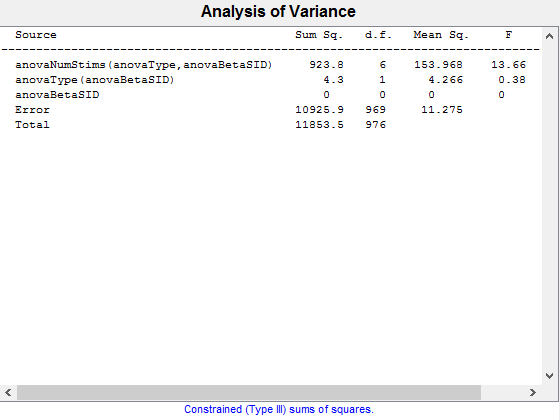

figure
[p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaType,anovaBetaSID},'varnames',{'anovaNumStims','anovaType','anovaBetaSID'},'model','interaction','nested',[0 1 1;0 0 1;0 0 0],'sstype',3)

p =     0.5807
       NaN


tbl =     'Source'                     'Sum Sq.'       'd.f.'    'Singular?'    'Mean Sq.'    'F'         'Prob>F'
    'anovaType(anovaBetaSID)'    [    3.7113]    [   1]    [        0]    [  3.7113]    [0.3054]    [0.5807]
    'anovaBetaSID'               [         0]    [   0]    [        0]    [       0]    [     0]    [   NaN]
    'Error'                      [1.1850e+04]    [ 975]    [        0]    [ 12.1536]          []          []
    'Total'                      [1.1853e+04]    [ 976]    [        0]            []          []          []


stats =          source: 'anovan'
          resid: [977x1 double]
         coeffs: [4x1 double]
            Rtr: [2x2 double]
       rowbasis: [2x4 double]
            dfe: 975
            mse: 12.1536
    nullproject: [4x2 double]
          terms: [2x2 double]
        nlevels: [2x1 double]
     continuous: [0 0]
         vmeans: [2x1 double]
       termcols: [3x1 double]
     coeffnames: {4x1 cell}
           vars: [4x2 double]
       varnames: {2x1 cell}
       grpnames: {2x1 cell}
        vnested: [2x2 double]
            ems: []
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


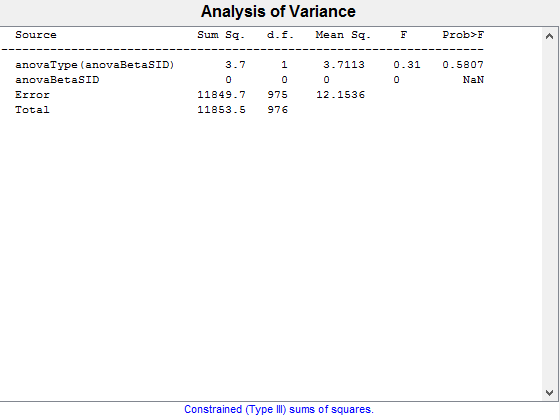

[p,tbl,stats] = anovan(anovaTotalMags,{anovaType,anovaBetaSID},'varnames',{'anovaType','anovaBetaSID'},'model','interaction','nested',[0 1; 0 0])

p =     0.0000
    0.5386
       NaN
    0.0015
       NaN
       NaN


tbl =     'Source'                        'Sum Sq.'       'd.f.'    'Singular?'    'Mean Sq.'    'F'          'Prob>F'    
    'anovaNumStims'                 [  652.4116]    [   3]    [        0]    [217.4705]    [19.2870]    [3.7552e-12]
    'anovaType'                     [    4.2664]    [   1]    [        0]    [  4.2664]    [ 0.3784]    [    0.5386]
    'anovaBetaSID'                  [         0]    [   0]    [        0]    [       0]    [      0]    [       NaN]
    'anovaNumStims*anovaType'       [  174.2429]    [   3]    [        0]    [ 58.0810]    [ 5.1511]    [    0.0015]
    'anovaNumStims*anovaBetaSID'    [         0]    [   0]    [        0]    [       0]    [      0]    [       NaN]
    'anovaType*anovaBetaSID'        [         0]    [   0]    [        0]    [       0]    [      0]    [       NaN]
    'Error'                         [1.0926e+04]    [ 969]    [        0]    [ 11.2755]           []              []
    'Total'                         [1.1853e+04]    [ 976]

stats =          source: 'anovan'
          resid: [977x1 double]
         coeffs: [22x1 double]
            Rtr: [8x8 double]
       rowbasis: [8x22 double]
            dfe: 969
            mse: 11.2755
    nullproject: [22x8 double]
          terms: [6x3 double]
        nlevels: [3x1 double]
     continuous: [0 0 0]
         vmeans: [3x1 double]
       termcols: [7x1 double]
     coeffnames: {22x1 cell}
           vars: [22x3 double]
       varnames: {3x1 cell}
       grpnames: {3x1 cell}
        vnested: []
            ems: []
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


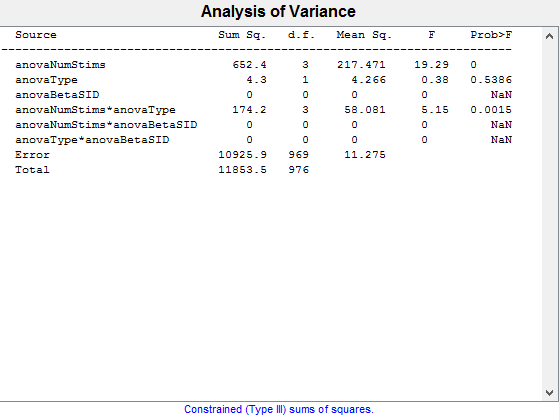

[p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaType,anovaBetaSID},'model','interaction','varnames',{'anovaNumStims','anovaType','anovaBetaSID'})

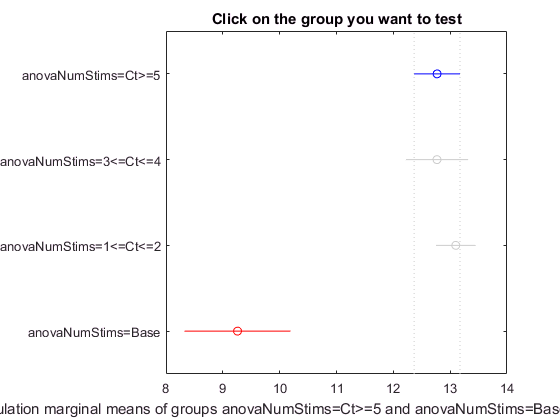

c =     1.0000    2.0000   -0.9682    0.0018    0.9718    1.0000
    1.0000    3.0000   -1.0535   -0.3293    0.3950    0.6471
    1.0000    4.0000    2.1649    3.5107    4.8565    0.0000
    2.0000    3.0000   -1.2365   -0.3310    0.5744    0.7837
    2.0000    4.0000    2.0575    3.5089    4.9603    0.0000
    3.0000    4.0000    2.5399    3.8399    5.1400    0.0000


m =    12.7696    0.2211
   12.7679    0.3060
   13.0989    0.1748
    9.2590    0.4749


h =   Figure (20: Multiple comparison of population marginal means) with properties:

      Number: 20
        Name: 'Multiple comparison of population marginal means'
       Color: [0.9400 0.9400 0.9400]
    Position: [680 678 560 420]
       Units: 'pixels'

  Show all properties


gnames =     'anovaNumStims=Ct>=5'
    'anovaNumStims=3<=Ct<=4'
    'anovaNumStims=1<=Ct<=2'
    'anovaNumStims=Base'



% [p,tbl,stats] = anovan(anovaTotalMags,{anovaType},'varnames',{'anovaType'})

figure
[c,m,h,gnames] = multcompare(stats)

[gnames num2cell(m)]

ans =     'anovaNumStims=Ct>=5'       [12.7696]    [0.2211]
    'anovaNumStims=3<=Ct<=4'    [12.7679]    [0.3060]
    'anovaNumStims=1<=Ct<=2'    [13.0989]    [0.1748]
    'anovaNumStims=Base'        [ 9.2590]    [0.4749]


figure
% bar(m(:,1))
% hold on
errorbar((1:length(m(:,1))),flip(m(:,1)),flip(m(:,2)),'ro','linestyle','none','linew',2','color','r')
% xlabel('Patients and Task','fontsize',16,'fontweight','bold')
ylabel('Zscored CCEP Magnitude','fontsize',14,'fontweight','bold')
xlabel('Number of Conditioning Pulses','fontsize',14,'fontweight','bold')

ax = gca;
ax.XTickLabelMode = 'manual'

ax =   Axes (CCEP Magnitude across Subjects) with properties:

             XLim: [0.5000 4.5000]
             YLim: [8 14]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1224 0.7750 0.7994]
            Units: 'normalized'

  Show all properties


ax.XTick = [1 2 3 4]

ax =   Axes (CCEP Magnitude across Subjects) with properties:

             XLim: [0.5000 4.5000]
             YLim: [8 14]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1224 0.7750 0.7994]
            Units: 'normalized'

  Show all properties


ax.XTickLabel = {'Baseline','1->2','3->4','>5' }

ax =   Axes (CCEP Magnitude across Subjects) with properties:

             XLim: [0.5000 4.5000]
             YLim: [8 14]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1224 0.7750 0.7994]
            Units: 'normalized'

  Show all properties


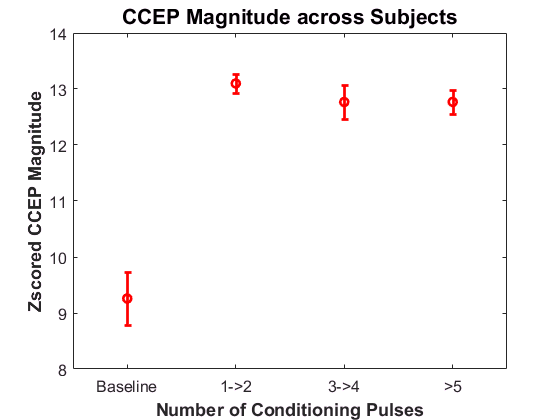

ax.FontSize = 12;
% ax.FontWeight = 'bold';
% set(gca,'XtickLabel',{'','>5','3->4', '1->2','Baseline'},'fontsize',14,'fontweight','bold')
title({'CCEP Magnitude across Subjects';},'fontsize',16,'fontweight','bold')

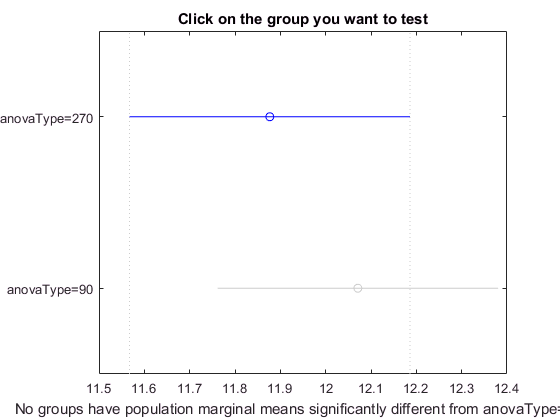

results1 =     1.0000    2.0000   -0.8129   -0.1942    0.4245    0.5385



figure
results1 = multcompare(stats,'Dimension',[2])

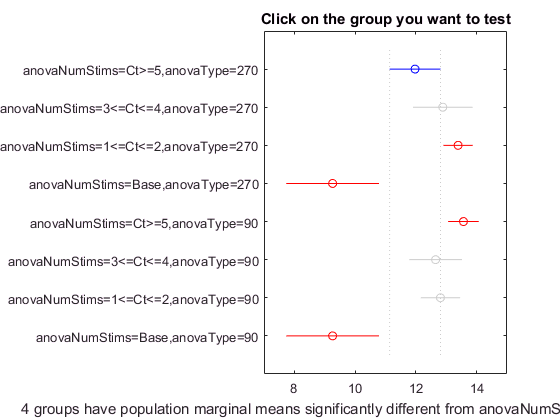

cM =     1.0000    2.0000   -2.7411   -0.9144    0.9124    0.7985
    1.0000    3.0000   -2.7330   -1.4167   -0.1003    0.0245
    1.0000    4.0000    0.3550    2.7134    5.0718    0.0115
    1.0000    5.0000   -2.9351   -1.5946   -0.2541    0.0075
    1.0000    6.0000   -2.3920   -0.6767    1.0386    0.9334
    1.0000    7.0000   -2.3291   -0.8365    0.6562    0.6884
    1.0000    8.0000    0.3550    2.7134    5.0718    0.0115
    2.0000    3.0000   -1.9963   -0.5023    0.9917    0.9717
    2.0000    4.0000    1.1658    3.6277    6.0897    0.0002
    2.0000    5.0000   -2.1956   -0.6802    0.8351    0.8750


mM =    11.9723    0.3930
   12.8867    0.4570
   13.3890    0.1848
    9.2590    0.6716
   13.5670    0.2029
   12.6490    0.4072
   12.8088    0.2968
    9.2590    0.6716


hM =   Figure (23: Multiple comparison of population marginal means) with properties:

      Number: 23
        Name: 'Multiple comparison of population marginal means'
       Color: [0.9400 0.9400 0.9400]
    Position: [680 678 560 420]
       Units: 'pixels'

  Show all properties


gnamesM =     'anovaNumStims=Ct>=5,anovaType=270'
    'anovaNumStims=3<=Ct<=4,anovaType=270'
    'anovaNumStims=1<=Ct<=2,anovaType=270'
    'anovaNumStims=Base,anovaType=270'
    'anovaNumStims=Ct>=5,anovaType=90'
    'anovaNumStims=3<=Ct<=4,anovaType=90'
    'anovaNumStims=1<=Ct<=2,anovaType=90'
    'anovaNumStims=Base,anovaType=90'




% figure
% results = multcompare(stats,'Dimension',[3])

figure
[cM,mM,hM,gnamesM] = multcompare(stats,'Dimension',[1 2])

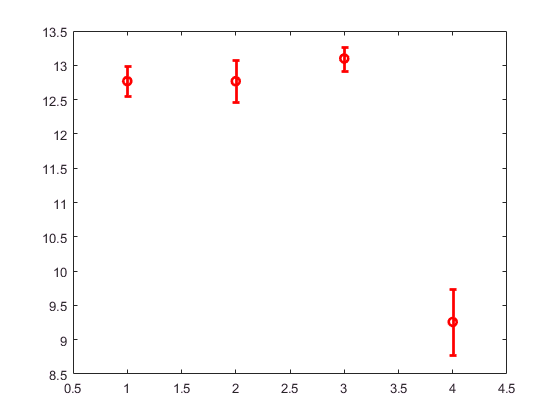

errorbar((1:length(m(:,1))),m(:,1),m(:,2),'ro','linestyle','none','linew',2','color','r')